% This file verify that the PID design and tuning give a correct output:

% 1) Step response verification in CST. step, stepinfo and margin commands are used 
% to verify the PID coefficients, considering:
% SettlingTime (must be lower or equal to 0.15 s)
% Overshoot ( must be lower or equal to 10% 
% Phase margin (near 60°)
% Cut off frequency (near 33 rad/s)

% 2) Verification of the step unitary response using a simplified simulink
% model: step_pid.slx (This model is not required in the assignments).

% 3) Verification of the step response using simulink Lab_0_sim.slx
% Lab_0_sim.slx contains the model required at point 2.1 in the Laboratory
% assignments. Steps amplitude: 10° 30° 50° 90° 180° 360° 

% Create the pid transfer function and the feedback transfer function

## Step response with simulink model (LAB_0_sim.slx) with amplitude 360 deg (Point 2.1.2)

% Define the step amplitude vector

simul.select1 = 1;

step_gain = 360;
simOut = sim('Lab_1\Point_2_1\2_1_1\Black_box_system_lab_1.slx');

### Searching for referenced models in model 'Black_box_system_lab_1'.
### Total of 0 models to build.


Found algebraic loop that contains: 
Black_box_system_lab_1/PID/Saturation  (discontinuity)
Black_box_system_lab_1/Quanser SRV-02 + NI DAQ1/DAC/Zero-Order Hold
Black_box_system_lab_1/Quanser SRV-02 + NI DAQ1/DAC/Quantizer (discontinuity)
Black_box_system_lab_1/Quanser SRV-02 + NI DAQ1/DAC/Saturation (discontinuity)
Black_box_system_lab_1/Quanser SRV-02 + NI DAQ1/Quanser SRV-02 (discontinuity)
<a href="matla

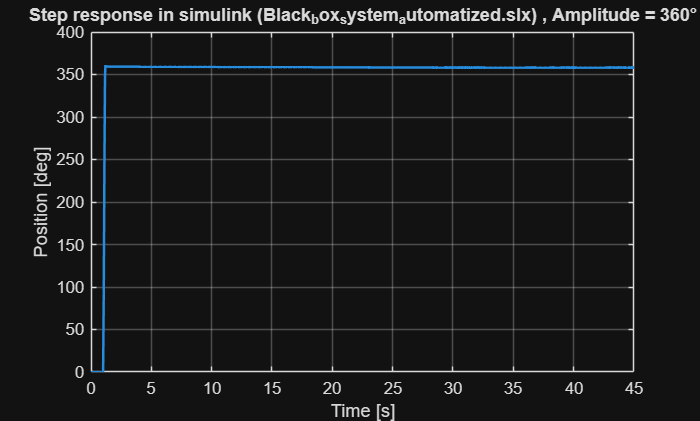


% Create plots
figure; 
plot(simOut.th.time,simOut.th.signals.values, 'LineWidth', 1.5);
grid on;
title(sprintf('Step response in simulink (Black_box_system_automatized.slx) , Amplitude = %d°', step_gain));
xlabel('Time [s]');
ylabel('Position [deg]');